addpath('Kinematics')
addpath('Kinetics')
addpath('Control System')

supressed_print= evalc('run Linearize_EOMs.mlx'); %Run the script to generate the equations of motion for the Ball and Plate in terms of the u-joint torques

clear supressed_print

sympref('FloatingPoint',true);

# Linear Moving Setpoint Controller

The feasibility of a setpoint controller for trajectory tracking is explored in this script. A setpoint controller with integral action is employed. The control law utilizes full state feedback to place the poles of the transfer function between the x setpoint and the x state. 

## Reformulate the System as Two Decoupled, Fourth Order, Single Input Systems

A system with state vector $\tilde{x}_{1} $:


$$\tilde{x}_{1} = [x ~\dot{x} ~\beta ~\dot{\beta}]^T

$$


And state equation:


$$\dot{\tilde{x}}_{1} = A_{1} \tilde{x}_{1} + B_{1}\tilde{u}_{1}$$


A1 = A_uc(1:4,1:4)

$$A1 = \left[\begin{array}{cccc} 0 & 1 & 0 & 0\\ -5.2170 & 0 & 4.0111 & 0\\ 0 & 0 & 0 & 1\\ 112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

B1 = B_uc(1:4,1)

$$B1 = \left[\begin{array}{c} 0\\ -17.7268\\ 0\\ 383.5785 \end{array}\right]$$

And another system with state vector $\tilde{x}_{2} $:


$$\tilde{x}_{2} = [y~\dot{y}~\gamma~\dot{\gamma}]^T$$


And state equation:


$$\dot{\tilde{x}}_{2} = A_{2} \tilde{x}_{2} + B_{2}\tilde{u}_{2}$$


A2 = A_uc(5:8,5:8)

$$A2 = \left[\begin{array}{cccc} 0 & 1 & 0 & 0\\ -5.2170 & 0 & -4.0111 & 0\\ 0 & 0 & 0 & 1\\ -112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

B2 = B_uc(5:8,2)

$$B2 = \left[\begin{array}{c} 0\\ 17.7268\\ 0\\ 383.5785 \end{array}\right]$$

## Augmented System For State Space Representation of Integral Controller

Using an augmented state vector this time:


$$\tilde{x}_{1a} = [
 \int_0^t \!e_x\, \mathrm{d}t~x ~\dot{x} ~\beta~\dot{\beta}]^T


$$


Where $e_x$ is the error in the $x$ position of the ball relative to $x_s$, the setpoint,


$$e_x = x_s - x$$


The new dynamics are found by differentiating the augmented state vector:


$$\dot{\tilde{x}}_{1a}  = 

\left\lbrack \begin{array}{c}

e_x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

= 

\left\lbrack \begin{array}{c}

x_s - x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack$$


$A_{1a}$ is the $A_1$ matrix modified to contain the dynamics of the $\int_{0}^{t}e_xdt~$term. This term's dynamics are the error itself, $e_x$, so the augmentation is a simple one. 

A1a = [zeros(5,1),[-1 0 0 0; A1]] %Augmented A1 Matrix

$$A1a = \left[\begin{array}{ccccc} 0 & -1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & -5.2170 & 0 & 4.0111 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & 112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

$B_{1a}$ is the direct influence of the actuation torque on the system. Since the integral of the error is not a direct function of this signal, the augmented matrix recieves another zero element. 

B1a = [0;B1]

$$B1a = \left[\begin{array}{c} 0\\ 0\\ -17.7268\\ 0\\ 383.5785 \end{array}\right]$$

$S_{1a}$ is the matrix that tells how the setpoint $x_s$ enters into the dynamics. It essentially derives from the definition of the error term and partially determines the dynamics of the $\int_{0}^{t}e_xdt~$term. 

S1a = sym([1;0;0;0;0])

$$B2a = \left[\begin{array}{c} 1\\ 0\\ 0\\ 0\\ 0 \end{array}\right]$$

Hence, the final equations of motion are:


$$

\left\lbrack \begin{array}{c}

e_x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

=

\left\lbrack \begin{array}{ccccc}
0 & -1 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0\\
0 & -5.2170 & 0 & 4.0111 & 0\\
0 & 0 & 0 & 0 & 1\\
0 & 112.8871 & 0 & 64.8295 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

 \int_0^t \!e_x\, \mathrm{d}t\\ x\\ \dot{x}\\ \beta\\ \dot{\beta}\\



\end{array}\right\rbrack

+ 

\left\lbrack \begin{array}{c}
0\\
0\\
-17.7268\\
0\\
383.5785
\end{array}\right\rbrack


T_{\beta }

+ 

\left\lbrack \begin{array}{c}
1\\
0\\
0\\
0\\
0
\end{array}\right\rbrack


x_s\\

$$


or in short: 


$$\dot{\tilde{x}}_{1a} = A_{1a}\tilde{x}_{1a} + B_{1a}T_\beta + S_{1a}{x}_{s}$$


## Create Data and Functions for Simulation (Moving Setpoint Controller)

A1a_sim = double(A1a);
B1a_sim = double(B1a);

Check controllability

rank(ctrb(A1a_sim, B1a_sim))

ans = 5

The system is fully controllable because the controllability matrix is full rank

S1a_sim = double(S1a);
C1a_setp_ctrl = [0 1 0 0 0]; %Only care about controlling the position to the desired trajectory through setpoint control (for now)

### Place the poles of the closed loop transfer function 


$$\frac{{X_s}(s)}{X(s)}  = C_{1a}(SI - (A_{1a} - B_{1a}K_1))^{-1}S_{1a} + D_1$$


where the matrices all belong to the augmented state space system. The effect is to avoid having to choose an integral gain in an architecuture of the form


$$\frac{{X_s}(s)}{X(s)}  = \frac{C(s)P(s)}{1 + C(s)P(s)$$


where $C(s)$ is an integral controller, $\frac{K_i}{s}$, and $P(s)$ is the open loop plant


$$P(s) = \frac{T_{\beta}(s)}{X(s)} = C_1(SI - A_1)^{-1}B_1 + D_1$$
 

With the augmented system, we can simply use full state feedback to arbitrarily place the poles of the integral controller rather than having to use three dimensional root locus techniques in our choice of $K_i$. 

K1a = place(A1a_sim,B1a_sim, [-1000 -2000 -3000 -4 -5]); 

### Moving Setpoint Parameters

r_sim = 50; % radius of circular trajectory [mm]
omega_sim =  2*pi/10; %angular frequency of circular trajectory 

des_traj_sym(t) = r_sim*sin(omega_sim*t)

$$des\_traj\_sym(t) = 50\,\sin\left(0.6283\,t\right)$$

des_traj_handle = matlabFunction(des_traj_sym)

des_traj_handle = function_handle with value:
    @(t)sin((t.*pi)./5.0).*5.0e+1


### Overlay a fist order response so that the desired trajectory is smoothed out a bit

T = (2*pi/omega_sim)/5 %Time constant of the first order response that smooths out the trajectory

T = 2

des_traj_sym(t) = (1 - exp(-(t/T)))*des_traj_sym

$$des\_traj\_sym(t) = -50\,\sin\left(0.6283\,t\right)\,\left({\mathrm{e}}^{-0.5000\,t}-1\right)$$

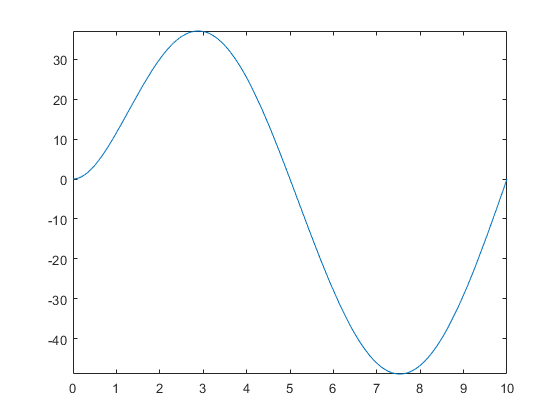

fplot(des_traj_sym) 
xlim([0 2*pi/omega_sim]);

## Simulate the Controller

%Specify simulation time
t_sim = 2*pi/omega_sim;
%Specify initial conditions
x1a_0 = [0 0 0 0 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system
%Select setpoint type
SP_sel = 1; %Sinusoidal input

out = sim('Linear_Moving_Setpoint')

out =   Simulink.SimulationOutput:

                   tout: [81044x1 double] 
                    x1a: [81044x5 double] 
                     y1: [81044x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 
